
	Correlation done between all ROIs, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only,  WHEN "rescaled" behaviour IS ongoing.
Using current obj.cc_mode : rescaled_peaks


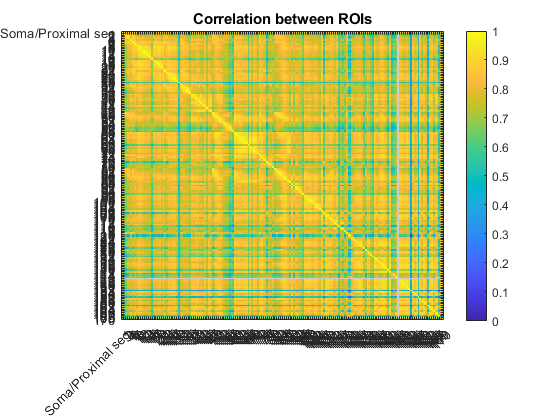

Using current obj.cc_mode : rescaled_peaks
total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

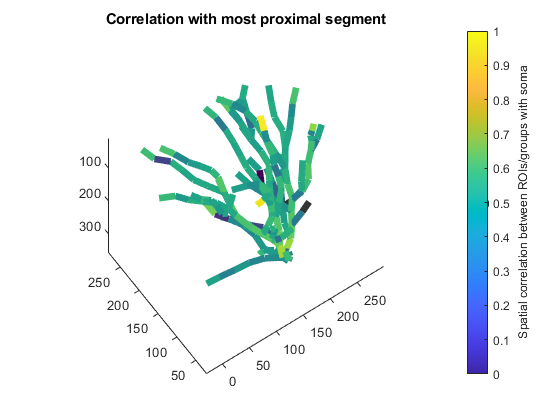

obj.filter_win = [10, 0];
obj.get_correlations('rescaled_peaks');


	Correlation done between all ROIs, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only,  WHEN "subtracted" behaviour IS ongoing.
Using current obj.cc_mode : subtracted_peaks


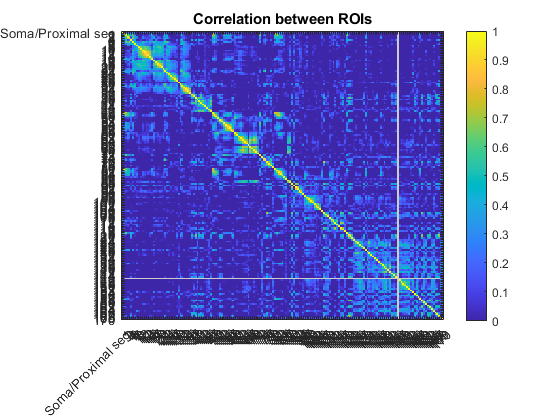

Using current obj.cc_mode : subtracted_peaks
total dendritic length (-excluded branches) : 3248 um


tree_aspect = 'simple'

ans = 1

obj.get_correlations('subtracted_peaks'); hold on

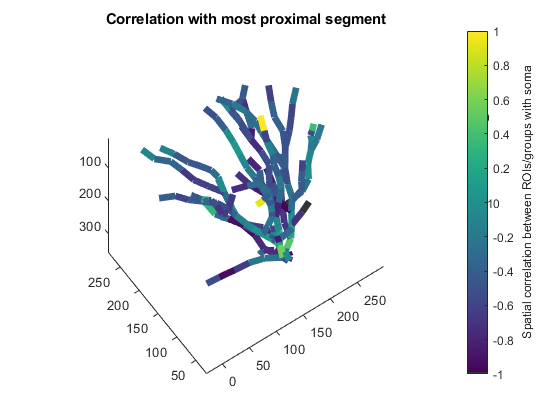

caxis([-1,1])


	Correlation done between all ROIs, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only,  WHEN "subtracted" behaviour IS ongoing.
Using current obj.cc_mode : subtracted_peaks
Using current obj.cc_mode : subtracted_peaks
total dendritic length (-excluded branches) : 980 um


tree_aspect = 'simple'

ans = 1

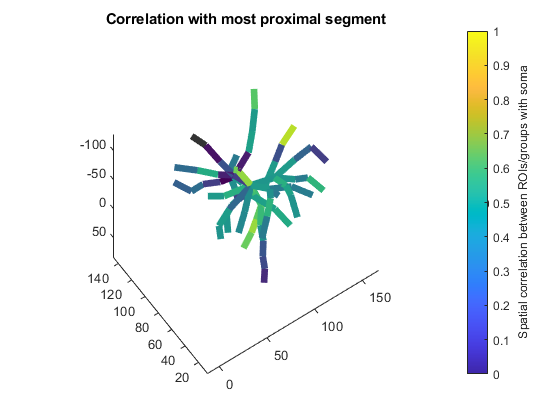

cross_corr = 69×69 single matrix
    1.0000   -0.0404    0.3834   -0.3250   -0.5096    0.0513   -0.2809    0.0394    0.0372    0.0239   -0.2695   -0.1848   -0.0884   -0.3448   -0.7421   -0.1767    0.0505    0.0402    0.3450    0.1265    0.0670    0.2572   -0.2846    0.5800    0.2223    0.1546   -0.3349   -0.1763   -0.5259   -0.5695   -0.3096    0.0249   -0.1973   -0.1080   -0.2395    0.3962   -0.3192   -0.3434   -0.6625    0.4421   -0.1561    0.4106    0.2828   -0.4397    0.2680   -0.3285   -0.3142    0.4935    0.2199    0.3836
   -0.0404    1.0000    0.1903    0.0457   -0.2150   -0.1805    0.0241   -0.3213   -0.5251   -0.3139   -0.1313   -0.1932   -0.0789   -0.2096   -0.2237    0.0664    0.0953    0.0472    0.2321    0.2972    0.4050    0.3185    0.0984    0.1408    0.2185    0.0305   -0.2329   -0.2717   -0.3840   -0.3169   -0.4223    0.1505   -0.1428    0.1630    0.0631    0.0031   -0.0134   -0.1552    0.0798    0.0400    0.5587   -0.0882    0.3929    0.3340   -0.4370    0.0983    0.

cross_corr = obj.get_correlations('subtracted_peaks')

% Note : you need to add to the path GenLouvain-master
[cluster_idx,Q] = genlouvain(double(cross_corr),[],[],1);

Merging 69 communities  19-Oct-2022 17:57:30
7 change: 121.3675 total: 121.3675 relative: 1
4 change: 21.7055 total: 143.073 relative: 0.15171
3 change: 17.0488 total: 160.1217 relative: 0.10647
3 change: 0.84572 total: 160.9675 relative: 0.005254
3 change: 0 total: 160.9675 relative: 0
Merging 3 communities  19-Oct-2022 17:57:31
3 change: 0 total: 160.9675 relative: 0


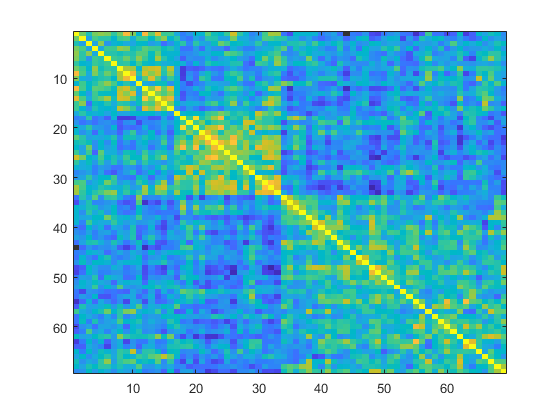

[a,b] = sort(cluster_idx);

cluster_idx = clusterdata(cross_corr,'Linkage', 'ward', 'MAXCLUST', 3);
[a,b] = sort(cluster_idx);
figure(1008);clf();imagesc(cross_corr(b,b))

total dendritic length (-excluded branches) : 980 um


tree_aspect = 'simple'

ans = 1

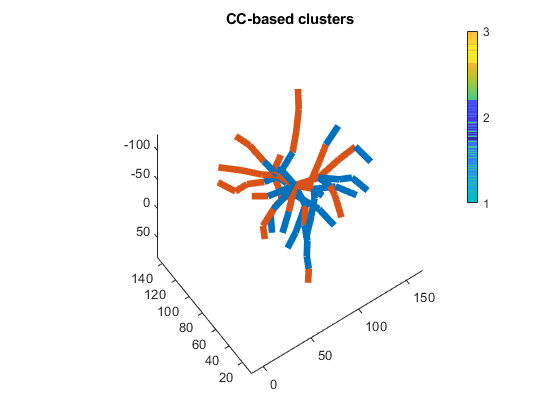

obj.ref.plot_value_tree(cluster_idx,'','','CC-based clusters','',124,'','lines','discrete');

% R = unique(cluster_idx);
% colorbar('Ticks',R);
% caxis([nanmin(R)-0.5, nanmax(R)+0.5])
% colormap(lines(numel(unique(cluster_idx))));

% 
% [S,Q] = genlouvain(double(cross_corr),[],[],1);
% [a,b] = sort(S);
% figure(1008);clf();imagesc(cross_corr(b,b))
% obj.ref.plot_value_tree(split_values_per_voxel(S, obj.ref.header.res_list(1:obj.ref.indices.n_tree_ROIs,1), signal_indices),'','','','',124,'','lines');
% R = unique(S);
% colorbar('Ticks',R);
% caxis([nanmin(R)-0.5, nanmax(R)+0.5])
% colormap(lines(numel(unique(S))));